load googlenet_2.mat
signds = imageDatastore("D:\college\FYP\Experimenting\test\stopping","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.8,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224],signTrain);
resizeTestImgs = augmentedImageDatastore([224 224],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",5,"VerboseFrequency",2);

% Training the network
[StopNetwork,info] = trainNetwork(resizeTrainImgs,googlenet_2,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:20 |       41.86% |       1.4788 |          0.0010 |
|       2 |           2 |       00:00:41 |       56.98% |       0.9099 |          0.0010 |
|       4 |           4 |       00:01:19 |       72.09% |       0.6591 |          0.0010 |
|       5 |           5 |       00:01:39 |       76.74% |       0.5129 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


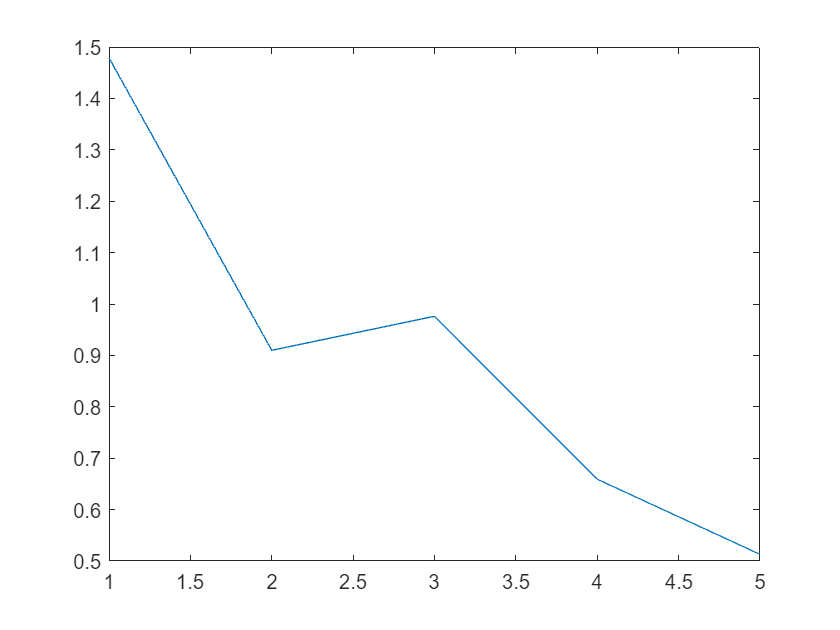


% Evaluating Performance
plot(info.TrainingLoss);

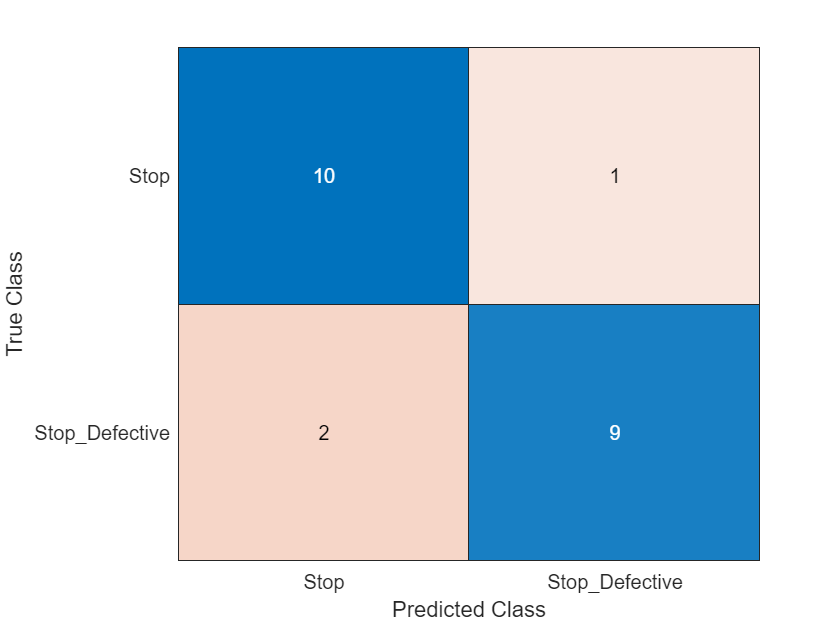



% Prediction
signPrediction = classify(StopNetwork,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);